# TA1: Identificación

IDENTIFICACIÓN DEL SISTEMA: RESPUESTA AL ESCALÓN Y PRBS

## DATOS DE SIMULACIÓN DEL ESCALÓN

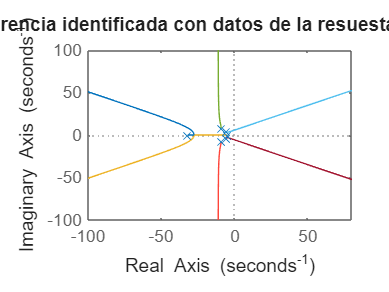

% Importar datos y guardarlos en vectores
datos_sim = readmatrix('datos_escalon_simulacion.DAT');

t_sim = datos_sim(:,1) - 3.006216984;
y_sim = datos_sim(:,2) - min(datos_sim(:,2));   % salida normalizada
u_sim = datos_sim(:,3) * (3/5);                 % entrada reescalada (el vector flag va de 1 a 5, lo modificamos para que sea de  0 a 3)

Ts_sim = mean(diff(t_sim)); % Tiepmo de muestreo

% Acá arreglamos errores en los datos de proteus
t_inicio = 0;
t_fin    = 6;
dt       = 0.001;

Npts = floor((t_fin - t_inicio)/dt);
i = 1;

Tt_sim = zeros(1, Npts);
u_sim_filt = zeros(1, Npts);
y_sim_filt = zeros(1, Npts);

for k = 1:Npts
    while (i < length(t_sim)) && (t_sim(i) < t_inicio + k*dt)
        i = i + 1;
    end
    Tt_sim(k) = (k-1)*dt;
    u_sim_filt(k) = u_sim(i);
    y_sim_filt(k) = y_sim(i);
end

u_sim_filt(1) = 0;

% Defino el objeto  para el system identification
data_sim_escalon = iddata(y_sim_filt', u_sim_filt', dt);

% Transferencia que escupe el system identification, 99% de coincidencia con
% la otra mitad de los datos

tf_6polos_escalon_simulacion = tf(1.158891170120908e+06 , [1,67.524408826597450,1.706768440587221e+03,2.303538442927073e+04,1.730485922460245e+05,6.943897404580413e+05,1.158357673009883e+06]);

rlocus(tf_6polos_escalon_simulacion);
title('ldr de la transferencia identificada con datos de la resuesta simulada al escalon');

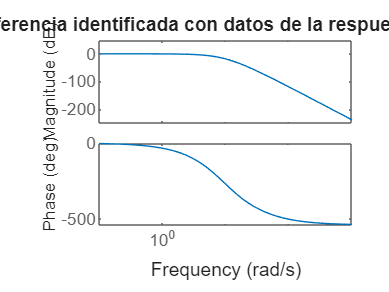

bode(tf_6polos_escalon_simulacion);
title('bode de la transferencia identificada con datos de la respuesta simualda al escalon');


% Aproximación FODPT (system id)
K_p = 1.0035

K_p = 1.0035

T = 0.2918 

T = 0.2918

L = 0.33292

L = 0.3329


s = tf("s");
G_sin_retardo = (K_p)/(1+s*T);
tf_fopdt_simulada = G_sin_retardo; 
tf_fopdt_simulada.InputDelay = L; 

## DATOS MEDIDOS DEL ESCALÓN REAL

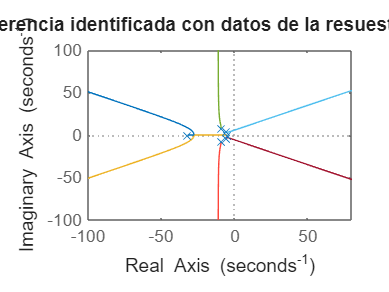

% Importar datos y guardarlos en vectores
datos_escalon = readtable('datos_escalon_medido.CSV');

t_escalon = datos_escalon.Var4(4:end) + 3; % corrige offset
T_escalon = mean(diff(t_escalon));

y_escalon = datos_escalon.Var5(4:end);
y_escalon = y_escalon - mean(y_escalon(1:6000));   % elimina offset

% Filtro pasabajos para sacarle los pelos
fs = 1/T_escalon;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

y_med_filt = filter(b_med, a_med, y_escalon);

% Acomodo el escalon para que quede entre 0 y 3 (funciona mejor en el sysid)
u_escalon = datos_escalon.Var6(4:end);
u_escalon(u_escalon < 4) = 0;
u_escalon(u_escalon >= 4) = 3;

% Defino el objeto  para el system identification
data_med_escalon = iddata(y_med_filt, u_escalon, T_escalon);

% Transferencia que escupe el system identification, 99.98% de coincidencia con
% la otra mitad de los datos

tf_6polos_escalon_medido = tf(1.158891170120908e+06 , [1,67.524408826597450,1.706768440587221e+03,2.303538442927073e+04,1.730485922460245e+05,6.943897404580413e+05,1.158357673009883e+06]);
rlocus(tf_6polos_escalon_medido);
title('ldr de la transferencia identificada con datos de la resuesta medida al escalon');

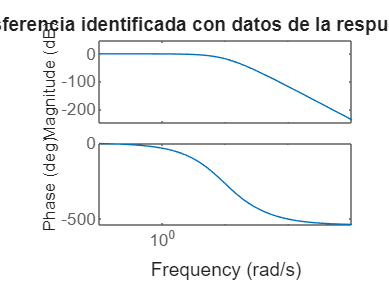

bode(tf_6polos_escalon_medido);
title('bode de la transferencia identificada con datos de la respuesta medida al escalon');

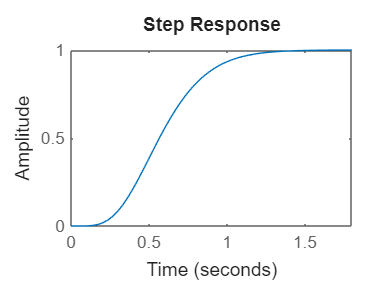

step(tf_6polos_escalon_medido);


% Aproximación FODPT (system id)
K_p = 0.98448

K_p = 0.9845

T = 0.33053 

T = 0.3305

L = 0.35938

L = 0.3594


G_sin_retardo = (K_p)/(1+s*T);
tf_fopdt_medida = G_sin_retardo; 
tf_fopdt_medida.InputDelay = L; 

tiempo_establecimiento_medido = 1.049 % incluye retardo

tiempo_establecimiento_medido = 1.0490

## TRANSFERENCIA IDEAL

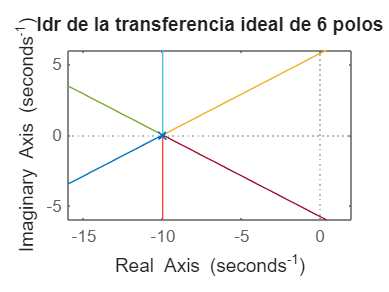

s = tf('s');
tf_6polos_ideal = 1/(s*0.1 + 1)^6;
rlocus(tf_6polos_ideal);
title('ldr de la transferencia ideal de 6 polos');

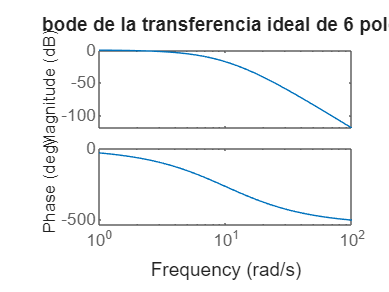

bode(tf_6polos_ideal);
title('bode de la transferencia ideal de 6 polos');

## DISEÑO PRBS

En base a los datos medidos de la respueta al escalón, tomamos los siguientes tiempos:

- Tes (tiempo de establecimiento al 5% + retardo) = 1.05 seg (de la respuesta al escalón medido)

- tau (al 63.2%, sin retardo) = 0.33  seg (de la aproximación FOPDT de sysid)

- L = 0.36 seg

***Primer diseño:***

*Elegimos Tmuestreo 10 veces menos que tau*

Tmuestreo = 0.33/10 = 0.033  seg

Definimos Tprbs = Tmuestreo/2 = 0.016 seg

*Calculamos N*

N.Tprbs > (tau + L)

De acá sale N = 0.69/0.016 seg = 43.1 (44 bits) (inviable)

*Calculamos cuando debe durar el ensayo:*

D = Tprbs$\left.{\left(2\right.}^n -1\right)=\;$0.016$\left.{\left(2\right.}^{44} -1\right)=\;$8925.5 años (jajaja)

***Segundo diseño***

*Elegimos Tmuestreo 2 veces menos que tau*

Iterando con distintos valores de N, definimos los Tprbs correspondientes, llegamos a definir la frecuencia de la prbs como el doble de tau. Calculamos la duración del ensayo D.

Tmuestreo = 0.33/2  < 0.165  seg

Definimos Tprbs < Tmuestreo/2 = 0.0825 seg, elegimos 0.065 seg

*Calculamos N*

N.Tprbs > (tau + L)

De acá sale N = 0.69/0.065 seg = 10.6 (11 bits)

N = 11 bits

*Recalculamos Tprbs para  los 11  bits redondeados:*

Tprbs = 65.65 ms

*Calculamos cuando debe durar el ensayo:*

D = 134.283 seg

*Verificamos que en el osciloscopio se pueda medir D a una frecuencia de muestro adecuada*

El osciloscopio utilizado, con base de tiempo de 10 segundos, tiene una frecuencia de muestreo 

de 200 Samples/seg, que cumple que es como mínimo 10 veces mayor que 1/Tprbs = fprbs = 15.23Hz. (13.13 veces mayor).

## DATOS MEDIDOS PRBS REAL

% Importar datos y guardarlos en vectores
datos_prbs = readtable('datos_prbs_medido.CSV');

T_prbs = 1/200;

% Vector salida
y_prbs = datos_prbs.Var1;
y_prbs = (y_prbs - 1000) / 3000;

y_prbs(y_prbs < 0) = 0; % recorto negativos

% Vector entrada
u_prbs = datos_prbs.Var2;
u_prbs(u_prbs < 2500) = 0;
u_prbs(u_prbs >= 2500) = 1;

% Defino el objeto  para el system identification
data_med_prbs = iddata(y_prbs, u_prbs, T_prbs);

% Transferencia que escupe el system identification, 92.35% de coincidencia con
% la otra mitad de los datos
tf_6polos_prbs_medida = tf_prbs_med6polos;
% tf_6polos_prbs_medida = tf([5.671618964260604e+05] , [1,58.284099674190490,1.284445491209403e+03,1.622971004687713e+04,1.087898782652298e+05,3.983829952470905e+05,5.775054615523315e+05]);

% Aproximación FODPT (system id)
K_p = 0.98257

K_p = 0.9826

T = 0.50484 

T = 0.5048

L = 0.34639

L = 0.3464


G_sin_retardo = (K_p)/(1+s*T);
tf_fopdt_prbs_medida = G_sin_retardo; 
tf_fopdt_prbs_medida.InputDelay = L; 

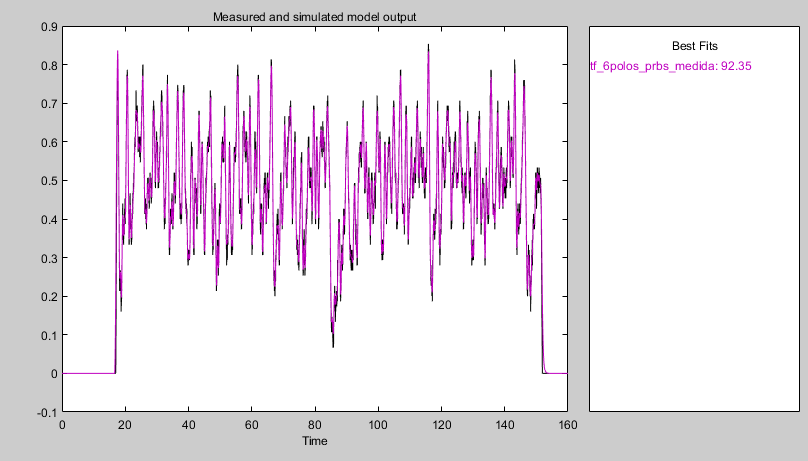 

Comparación de la respuesta del modelo generado de 6 polos con los datos reales

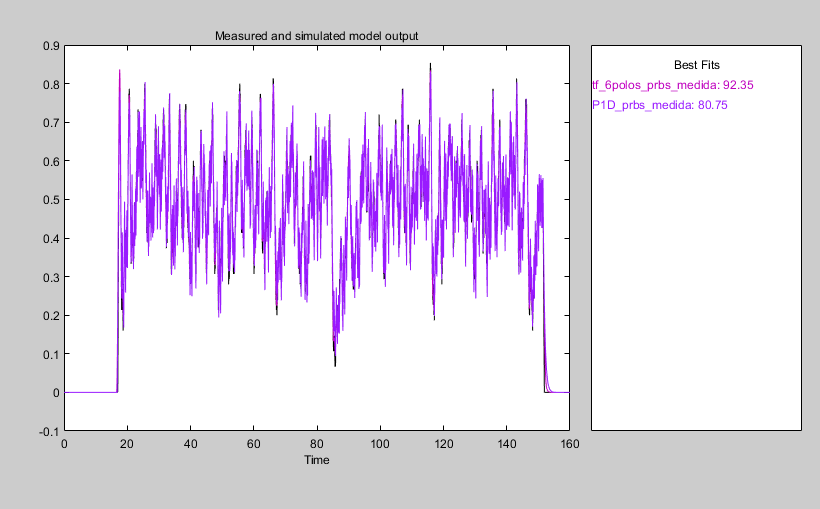

Comparación de la respuesta del modelo generado de orden 1 con los datos reales

## ANÁLISIS DE LA APROXIMACIÓN FOPDT FINAL (PRBS)

Basado en el modelo obtenido en el ensayo de PRBS y del escalón, se obtuvo:


$$\begin{array}{l}
G_{\textrm{FOPDT}} =\frac{K_p e^{-\textrm{Ls}} }{1+\textrm{Ts}}=\frac{\left(0\ldotp 98257\right)e^{-\left(0\ldotp 34639\right)s} }{1+\left(0\ldotp 50484\right)s}\\
T=0\ldotp 50484\\
L=0\ldotp 34639\\
K_{p\;} =0\ldotp 98257
\end{array}$$


% Defino el modelo FOPDT 
s = tf('s');

T =  0.27;
L  = 0.37;
K_p = 1;

G_sin_retardo = (K_p)/(1+s*T);
G_fopdt = G_sin_retardo; 
G_fopdt.InputDelay = L; 
tf_fopdt_prbs_medida = G_fopdt;
tf_fopdt_ideal = G_fopdt


tf_fopdt_ideal =
 
                     1
  exp(-0.37*s) * ----------
                 0.27 s + 1
 
Continuous-time transfer function.
Model Properties


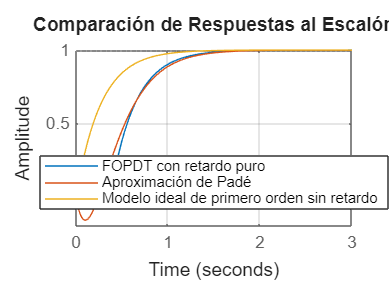

G_aprox = G_sin_retardo*(1-(s*L/2))/(1+(s*L/2));  %  Aproximado por Padé

% grafico

figure;
h = stepplot(G_fopdt, G_aprox, G_sin_retardo);
grid on;
title("Comparación de Respuestas al Escalón");

legend( ...
    'FOPDT con retardo puro', ...
    'Aproximación de Padé', ...
    'Modelo ideal de primero orden sin retardo', ...
    'Location','best' );

## COMPARACIÓN DE LOS RESULTADOS

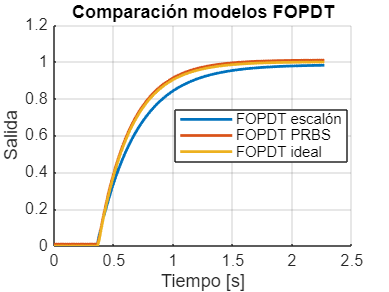

%% Eje temporal común (tomado del FOPDT medido al escalón)
[y_fopdt_step, t] = step(tf_fopdt_medida);

%% Respuestas FOPDT
y_fopdt_prbs   = step(tf_fopdt_prbs_medida, t);
y_fopdt_ideal  = step(tf_fopdt_ideal, t);

%% Respuestas 6 polos
y_6polos_step  = step(tf_6polos_escalon_medido, t);
y_6polos_prbs  = step(tf_6polos_prbs_medida, t);
y_6polos_ideal = step(tf_6polos_ideal, t);

%% =========================
% 1) Comparación FOPDT
%% =========================
figure; grid on; hold on;
plot(t, y_fopdt_step,  'LineWidth', 1.6);
plot(t, y_fopdt_prbs+.01,  'LineWidth', 1.6);
plot(t, y_fopdt_ideal, 'LineWidth', 1.6);
xlabel('Tiempo [s]');
ylabel('Salida');
title('Comparación modelos FOPDT');
legend('FOPDT escalón','FOPDT PRBS','FOPDT ideal','Location','best');
hold off;

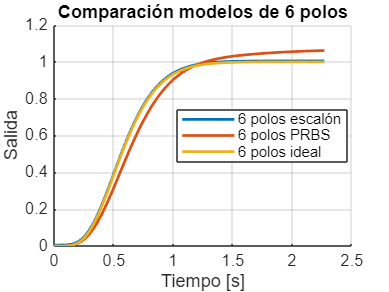


%% =========================
% 2) Comparación 6 polos
%% =========================
figure; grid on; hold on;
plot(t, y_6polos_step+0.005,  'LineWidth', 1.6);
plot(t, y_6polos_prbs,  'LineWidth', 1.6);
plot(t, y_6polos_ideal, 'LineWidth', 1.6);
xlabel('Tiempo [s]');
ylabel('Salida');
title('Comparación modelos de 6 polos');
legend('6 polos escalón','6 polos PRBS','6 polos ideal','Location','best');
hold off;

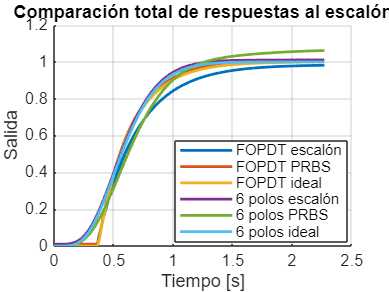


%% =========================
% 3) Comparación total
%% =========================
figure; grid on; hold on;
plot(t, y_fopdt_step,   'LineWidth', 1.6);
plot(t, y_fopdt_prbs+0.01,   'LineWidth', 1.6);
plot(t, y_fopdt_ideal,  'LineWidth', 1.6);
plot(t, y_6polos_step+.01,  'LineWidth', 1.6);
plot(t, y_6polos_prbs,  'LineWidth', 1.6);
plot(t, y_6polos_ideal, 'LineWidth', 1.6);
xlabel('Tiempo [s]');
ylabel('Salida');
title('Comparación total de respuestas al escalón');
legend( ...
    'FOPDT escalón', ...
    'FOPDT PRBS', ...
    'FOPDT ideal', ...
    '6 polos escalón', ...
    '6 polos PRBS', ...
    '6 polos ideal', ...
    'Location','best');
hold off;

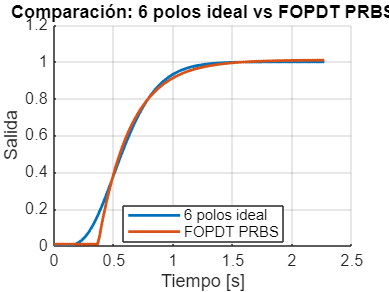


figure; grid on; hold on;
plot(t, y_6polos_ideal,        'LineWidth', 1.6);
plot(t, y_fopdt_prbs + 0.01,   'LineWidth', 1.6);

xlabel('Tiempo [s]');
ylabel('Salida');
title('Comparación: 6 polos ideal vs FOPDT PRBS');

legend( ...
    '6 polos ideal', ...
    'FOPDT PRBS', ...
    'Location','best');

hold off;

## 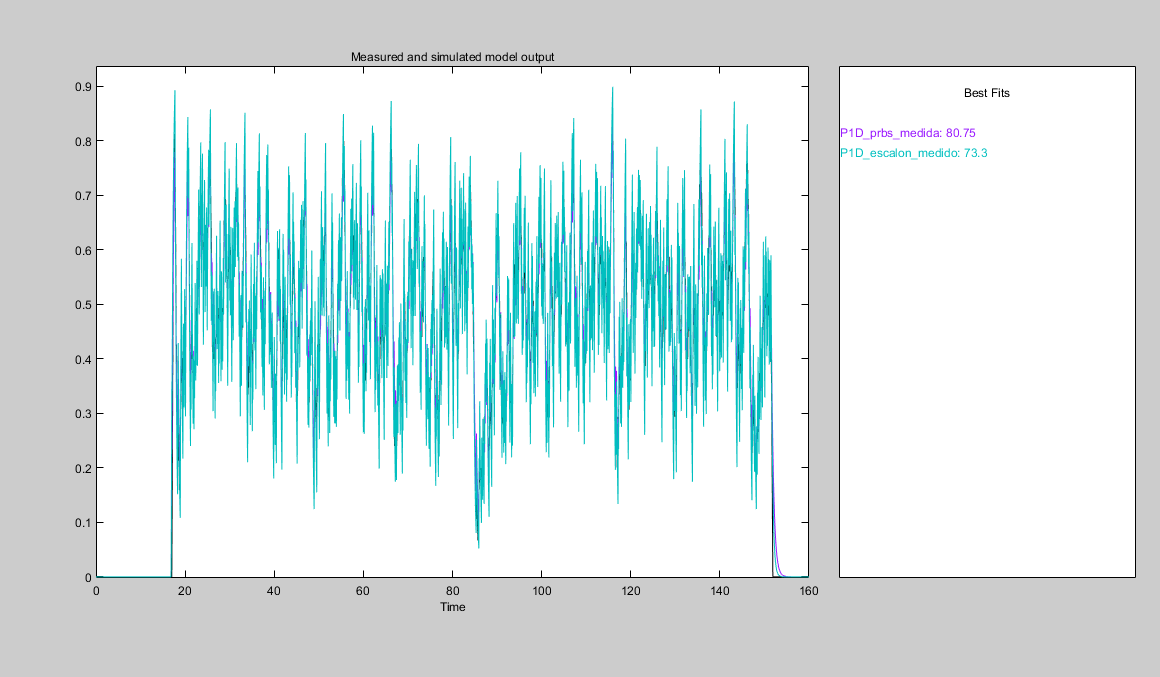

Respuesta a la PRBS de las  transferencias FOPDT de prbs y escalon.